**System 1**

a=19;
b=8;
c=a+b;

**Lead Compensator**

G1=tf([a],[b c])

G1 =
 
     19
  --------
  8 s + 27
 
Continuous-time transfer function.



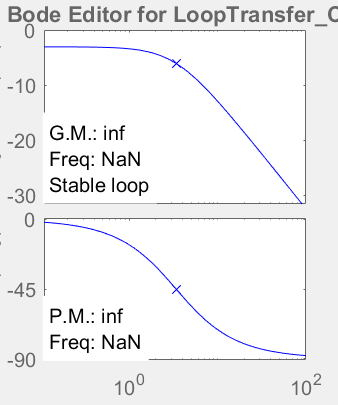

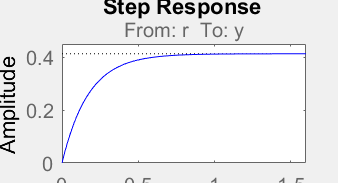

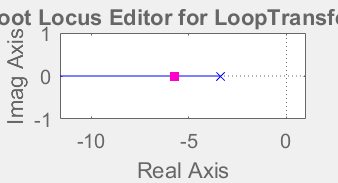

%sisotool(G1)

Ess1=10/100;
kG1=a/c

kG1 = 0.7037

kC1=(1-Ess1)/(Ess1*kG1)

kC1 = 12.7895

xG1=-5;
yG1=-9;
zG1=(yG1*kC1)/xG1

zG1 = 23.0211

C1=zpk([xG1],[yG1],[zG1])

C1 =
 
  23.021 (s+5)
  ------------
     (s+9)
 
Continuous-time zero/pole/gain model.



**Lead-Lag Compensator**

EssL1=5/100;
%Lead
kG1_LC=a/c

kG1_LC = 0.7037

kC1_LC=xG1*zG1/yG1

kC1_LC = 12.7895

C1_LC=zpk([xG1],[yG1],[zG1])

C1_LC =
 
  23.021 (s+5)
  ------------
     (s+9)
 
Continuous-time zero/pole/gain model.




%Lag
kC1_LgC=(1-EssL1)/(EssL1*kG1_LC*kC1_LC)

kC1_LgC = 2.1111

xlg1=-4;
ylg1=xlg1/kC1_LgC

ylg1 = -1.8947

C1_LgC=zpk([xlg1],[ylg1],[1])

C1_LgC =
 
    (s+4)
  ---------
  (s+1.895)
 
Continuous-time zero/pole/gain model.



C1_C=C1_LC*C1_LgC

C1_C =
 
  23.021 (s+5) (s+4)
  ------------------
   (s+9) (s+1.895)
 
Continuous-time zero/pole/gain model.

